## Load Display Info

presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.50);

## Create First Stimulus: Orientation = 0 deg

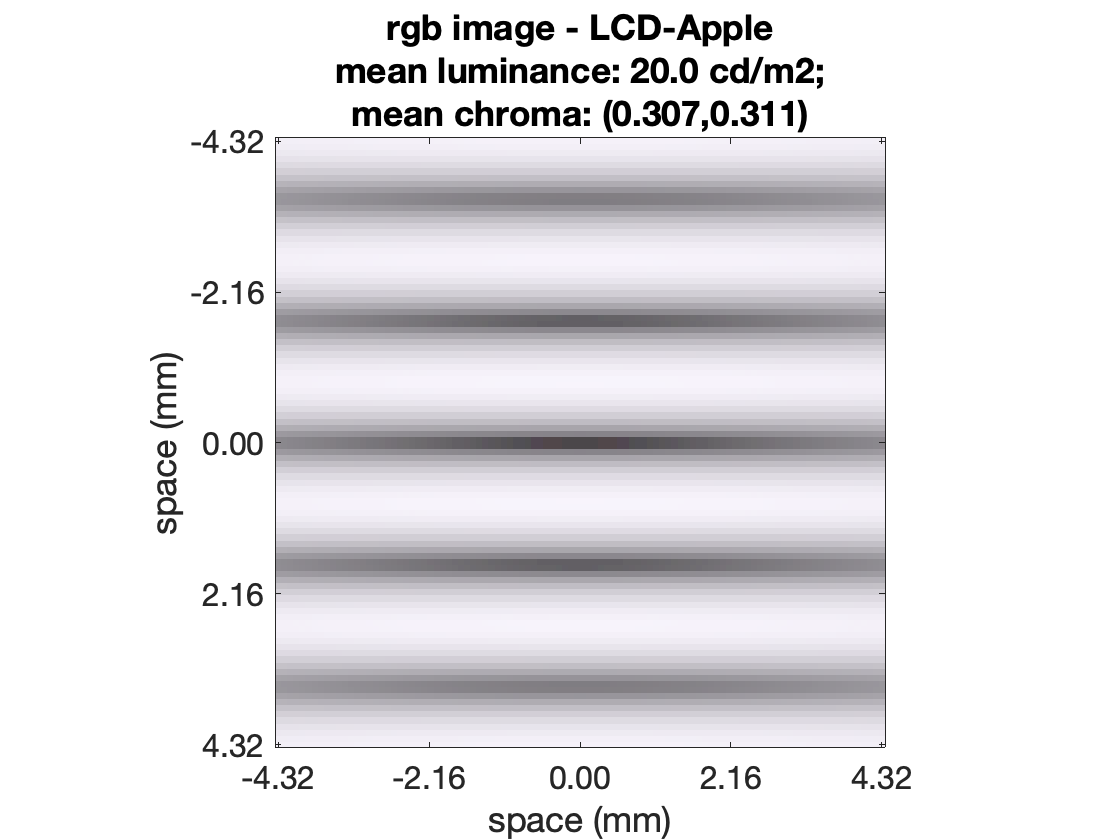

% Parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg',5, ... 
    'orientationDegs', 90, ...               
    'phaseDegs', 180, ...                    
    'sizeDegs', 1, ...                    
    'sigmaDegs', 3/3, ...                 
    'contrast', 100/100,...                  
    'meanLuminanceCdPerM2', 20, ...
    'center', [0 0], ...
    'pixelsAlongWidthDim', 512, ...          
    'pixelsAlongHeightDim', 512 ... 
    ); % 

% scene1 = generateGaborScene(...
%     'stimParams', stimParams,...
%     'presentationDisplay', presentationDisplay, ...
%     'minimumPixelsPerHalfPeriod', 10);

scene1 = generateGaborSceneCustomize(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 10);

% Visualize the generated scene
visualizeScene(scene1, ...
    'displayRadianceMaps', false);

## Create Second Stimulus: Orientation = 90 deg

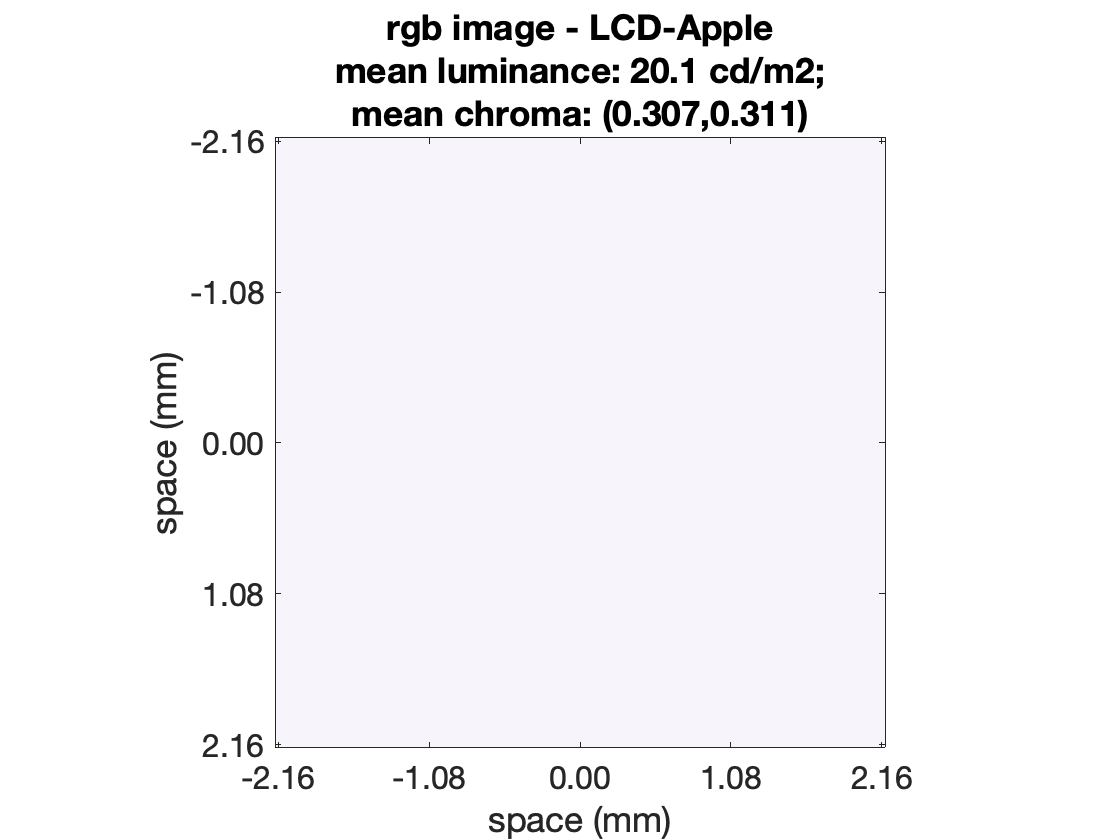

stimParams.contrast = 0;

scene2 = generateGaborSceneCustomize(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 10);

% Visualize the generated scene
visualizeScene(scene2, ...
    'displayRadianceMaps', false);

## Create Optical Image for these two scenes

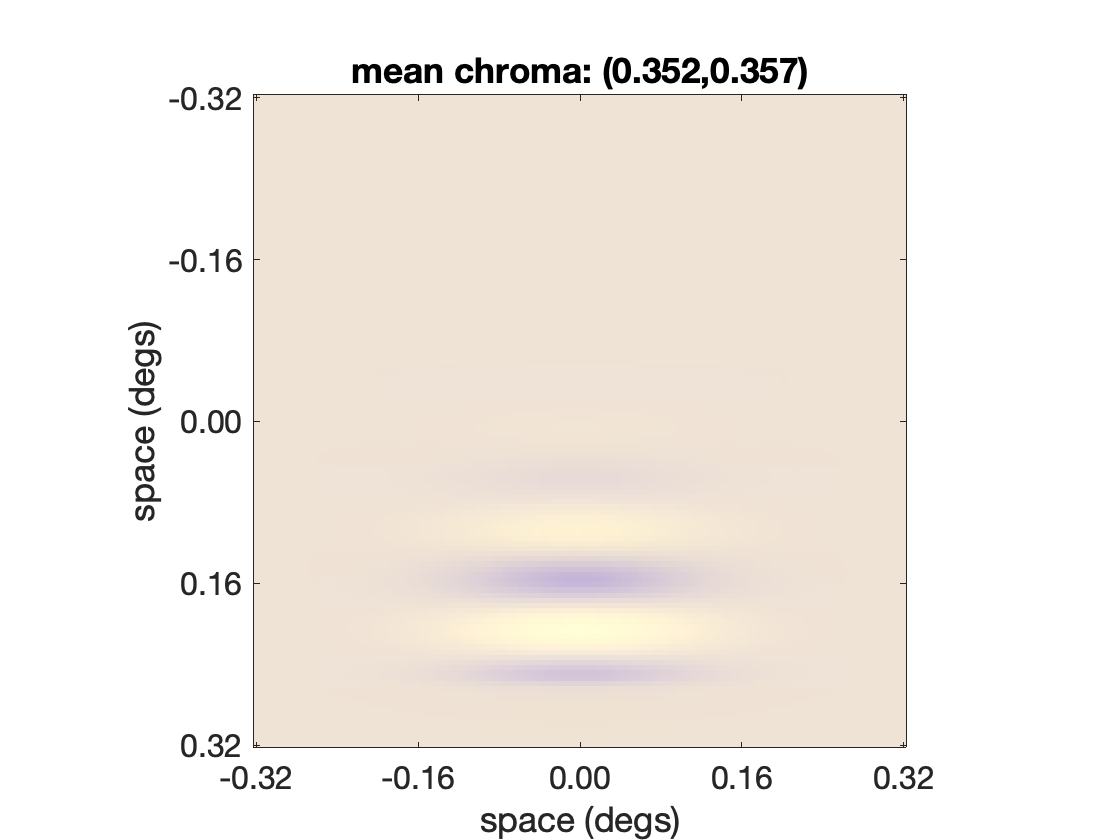

% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

% Compute the retinal image of the test stimulus
OI_1 = oiCompute(theOI, scene1);
% Compute the retinal image of the null stimulus
OI_2 = oiCompute(theOI, scene2);

% Visualize the optical image of the test
visualizeOpticalImage(OI_1, ...
    'displayRadianceMaps', false);

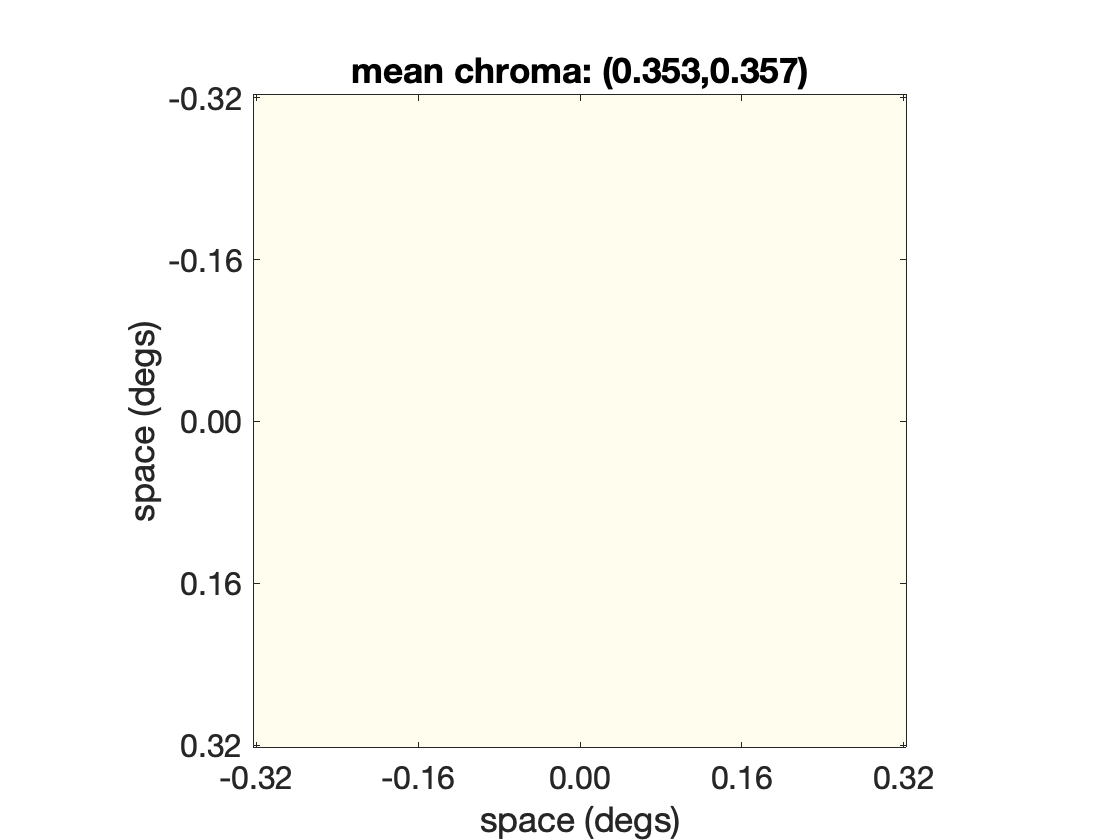

% Visualize the optical image of the test
visualizeOpticalImage(OI_2, ...
    'displayRadianceMaps', false);

## Pipeline: Create scene and on display

% Stimulus 1 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... 
    'orientationDegs', 90, ...               
    'phaseDegs', 180, ...                    
    'sizeDegs', 0.5, ...                    
    'sigmaDegs', 0.2/3, ...                 
    'contrast', 6/100,...                  
    'meanLuminanceCdPerM2', 20, ...         
    'pixelsAlongWidthDim', [], ...          
    'pixelsAlongHeightDim', [] ...          
    );
scene1 = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 10);
% Stimulus 2
stimParams.contrast = 0;
scene2 = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 10);
% visualizeScene(scene1, ...
%     'displayRadianceMaps', false);
% visualizeScene(scene2, ...
%     'displayRadianceMaps', false);

% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');
OI_1 = oiCompute(theOI, scene1);
OI_2 = oiCompute(theOI, scene2);
% visualizeOpticalImage(OI_1, ...
%     'displayRadianceMaps', false);
% visualizeOpticalImage(OI_2, ...
%     'displayRadianceMaps', false);

## Create Cone Mosaic

integrationTime = 50;
% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = cMosaic('sizeDegs', [1, 1] * stimParams.sizeDegs, ... 
            'integrationTime', integrationTime / 1000); % 10 msec integration time

Loading cone mosaic data from /Users/qiyuanfeng/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/right_eye_cones_58deg_mosaic.
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## Compute cone response

% with eye movement
duration = 100 / 1000;
nTrials = (duration*1000) / integrationTime;
nTrialsNum = 50;
noisyExcitationResponseInstances1 = zeros(nTrialsNum, nTrials, 3822);
noisyExcitationResponseInstances2 = zeros(nTrialsNum, nTrials, 3822);
noiseFreeExcitationResponseInstances1 = zeros(nTrialsNum, nTrials, 3822);
noiseFreeExcitationResponseInstances2 = zeros(nTrialsNum, nTrials, 3822);
for i = 1:nTrialsNum
    theMosaic.emGenSequence(duration, 'nTrials', nTrials, 'centerPaths', true,'microsaccadeType', 'none');
    [noiseFreeExcitationResponseInstances_11,noisyExcitationResponseInstances_11, PC1,PC2,timeAxis1] = theMosaic.compute(OI_1, 'nTrials', 1, 'withFixationalEyeMovements', true);
    noisyExcitationResponseInstances1(i,:,:) = noisyExcitationResponseInstances_11;
    noiseFreeExcitationResponseInstances1(i,:,:) = noiseFreeExcitationResponseInstances_11;
    [noiseFreeExcitationResponseInstances_22,noisyExcitationResponseInstances_22, ~,~,~] = theMosaic.compute(OI_2, 'nTrials', 1, 'withFixationalEyeMovements', true);
    noisyExcitationResponseInstances2(i,:,:) = noisyExcitationResponseInstances_22;
    noiseFreeExcitationResponseInstances2(i,:,:) = noiseFreeExcitationResponseInstances_22;
end

% % without eye movement
% [noiseFreeExcitationResponseInstances1_noFEM,noisyExcitationResponseInstances1_noFEM, PC1,PC2,timeAxis3] = theMosaic.compute(OI_1, 'nTrials', nTrialsNum, 'withFixationalEyeMovements', false);
% [~,~,PC3,PC4,PC5] = theMosaic.compute(OI_2, 'nTrials', nTrialsNum, 'withFixationalEyeMovements', false);

## Compare Cone Mosaic Excitation Response

mean(noiseFreeExcitationResponseInstances1_noFEM)

Unrecognized function or variable 'noiseFreeExcitationResponseInstances1_noFEM'.

mean(noiseFreeExcitationResponseInstances2_noFEM)

## Visualize Cone Mosaic Excitation

[meanNoiseFree1,meanNoisy1] = visualizeConeExcitation(noiseFreeExcitationResponseInstances1, noisyExcitationResponseInstances1, timeAxis1, 'false'); % 1 x nEye(20)
[meanNoiseFree1_noEM,meanNoisy1_noEM] = visualizeConeExcitation(noiseFreeExcitationResponseInstances1_noFEM, noisyExcitationResponseInstances1_noFEM, timeAxis3, 'false'); % 1 x nEye(20)
mean(meanNoiseFree1)
mean(meanNoisy1)
mean(meanNoiseFree1_noEM)
mean(meanNoisy1_noEM)
[meanNoiseFree2,meanNoisy2] = visualizeConeExcitation(noiseFreeExcitationResponseInstances2, noisyExcitationResponseInstances2, timeAxis1, 'false');
mean(meanNoiseFree2)
mean(meanNoisy2)
[meanNoiseFree2_noEM,meanNoisy2_noEM] = visualizeConeExcitation(noiseFreeExcitationResponseInstances2_noFEM, noisyExcitationResponseInstances2_noFEM, timeAxis3, 'false'); % 1 x nEye(20)
mean(meanNoiseFree2_noEM)
mean(meanNoisy2_noEM)

## With Eye Movement: PCA & SVM

% Simulate a 2AFC task 
taskIntervals = 2;
[classificationMatrix, classLabels] = generateSetUpForClassifier(...
    noisyExcitationResponseInstances1, noisyExcitationResponseInstances2, taskIntervals);

% Find principal components of the responses
[pcVectors, ~, ~, ~,varianceExplained] = pca(classificationMatrix);

% Project the responses onto the space formed by the first 4 PC vectors
pcComponentsNumForClassification = 2;
classificationMatrixProjection = classificationMatrix * pcVectors(:,1:pcComponentsNumForClassification);

% Visualize the classification matrix and its projection to the PC space
visualizeClassificationMatrices(classificationMatrix, classificationMatrixProjection, taskIntervals)
% Train a binary SVM classifier & Measure performance

% Train a binary SVM classifier and visualize the support vectors in 2
% dimensions
svm = fitcsvm(classificationMatrixProjection,classLabels);

% Visualize the data along with the hyperplane computed by the SVM 
visualizeSVMmodel(svm, classificationMatrixProjection, classLabels);
% Measure performance of the SVM classifier using a 10-fold crossvalidation
% approach
% Perform a 10-fold cross-validation on the trained SVM model
kFold = 10;
CVSVM = crossval(svm,'KFold',kFold);

% Compute classification loss for the in-sample responses using a model 
% trained on out-of-sample responses
fractionCorrect = 1 - kfoldLoss(CVSVM,'lossfun','classiferror','mode','individual');
% Average percent correct across all folds 
percentCorrect = mean(fractionCorrect)*100

## Without Eye Movement: PCA & SVM

% Simulate a 2AFC task 
taskIntervals = 2;
[classificationMatrix, classLabels] = generateSetUpForClassifier_noEM(...
    noisyExcitationResponseInstances1_noFEM, noisyExcitationResponseInstances2_noFEM, taskIntervals);

% Find principal components of the responses
[pcVectors, ~, ~, ~,varianceExplained] = pca(classificationMatrix);

% Project the responses onto the space formed by the first 4 PC vectors
pcComponentsNumForClassification = 2;
classificationMatrixProjection = classificationMatrix * pcVectors(:,1:pcComponentsNumForClassification);

% Visualize the classification matrix and its projection to the PC space
visualizeClassificationMatrices(classificationMatrix, classificationMatrixProjection, taskIntervals)
% Train a binary SVM classifier and visualize the support vectors in 2
% dimensions
svm = fitcsvm(classificationMatrixProjection,classLabels);

% Visualize the data along with the hyperplane computed by the SVM 
visualizeSVMmodel(svm, classificationMatrixProjection, classLabels);
% Measure performance of the SVM classifier using a 10-fold crossvalidation approach
% Perform a 10-fold cross-validation on the trained SVM model
kFold = 10;
CVSVM = crossval(svm,'KFold',kFold);

% Compute classification loss for the in-sample responses using a model 
% trained on out-of-sample responses
fractionCorrect = 1 - kfoldLoss(CVSVM,'lossfun','classiferror','mode','individual');
% Average percent correct across all folds 
percentCorrect = mean(fractionCorrect)*100

## figure

x = [10,15,20,25,30,35,40,45,50];
y1 = accuracy_noFEM;
y2 = accuracy_FEM;
plot(x,y1,'-ok','LineWidth',3)
hold on
plot(x,y2,'-ob','LineWidth',3)
title('SVM Acuracy while changing stimulus luminance (contrast = 15)')
xlabel('Luminance (%)')
ylabel('Accuracy (%)')
legend('no eye movement','with eye movement')
hold off

## V. Add Eye Movement Data & Visualize responses

duration = 400 / 1000;
t1Msec = 300;
t2Msec = 320;
nTrials = 20;
hFig = figure(1);
ax = subplot(1,2,1);
theMosaic.emGenSequence(duration, 'nTrials', nTrials, 'centerPaths', true,'microsaccadeType', 'none');
temporalSupportMsec = 1000*theMosaic.fixEMobj.timeAxis;
[~,timePoint1] = min(abs(temporalSupportMsec-t1Msec));
[~,timePoint2] = min(abs(temporalSupportMsec-t2Msec));
t1Msec = temporalSupportMsec(timePoint1);
t2Msec = temporalSupportMsec(timePoint2);
theMosaic.visualize('figureHandle', hFig, 'axesHandle', ax, ...
    'crossHairsOnMosaicCenter', true, ...
    'displayedEyeMovementData', struct('trial', 1:nTrials, 'timePoints', timePoint1:timePoint2), ...
    'plotTitle', sprintf('fEM data: %2.0f - %2.0f msec\n(centered paths)', t1Msec, t2Msec));
% ax = subplot(1,2,2);
% theMosaic.emGenSequence(duration, 'nTrials', nTrials, 'centerPaths', false,'microsaccadeType', 'none');
% theMosaic.visualize('figureHandle', hFig, 'axesHandle', ax, ...
%     'crossHairsOnMosaicCenter', true, ...
%     'displayedEyeMovementData', struct('trial', 1:nTrials, 'timePoints', timePoint1:timePoint2), ...
%     'plotTitle', sprintf('fEM data: %2.0f - %2.0f msec', t1Msec, t2Msec));

## X. Stimulus 1: Visualize time series cone mosaic response (noise-free)

hFig = figure(3); clf;
set(hFig, 'Position', [100 300 1120 1060]);
activationRange = prctile(noiseFreeExcitationResponseInstances1(:), [1 99]);
subplotPos = NicePlot.getSubPlotPosVectors(...
       'rowsNum', 4, ...
       'colsNum', 5, ...
       'heightMargin',  0.03, ...
       'widthMargin',    0.03, ...
       'leftMargin',     0.03, ...
       'rightMargin',    0.03, ...
       'bottomMargin',   0.03, ...
       'topMargin',      0.03);
for timePoint = 1:size(noiseFreeExcitationResponseInstances1,2)
    if (timePoint <= 20)
        row = floor((timePoint-1)/5)+1;
        col = mod(timePoint-1,5)+1;
        ax = subplot('Position', subplotPos(row,col).v);
        theMosaic.visualize('figureHandle', hFig, 'axesHandle', ax, ...
             'activation', noiseFreeExcitationResponseInstances1(1,timePoint,:), ...
             'activationRange', activationRange, ...
             'crossHairsOnOpticalImageCenter', true, ...
             'currentEMposition', squeeze(emPaths(1,timePoint,:)), ...
             'displayedEyeMovementData', struct('trial', 1, 'timePoints', 1:timePoint), ...
             'noXLabel', true, 'noYLabel', true, ...
             'plotTitle',  sprintf('%2.0f msec', timeAxis1(timePoint)*1000));
    end
    
end

## V. Visualize Cone Mosaic Excitation Responses for Stimulus 2

[noiseFreeExcitationResponseInstances2, noisyExcitationResponseInstances2, ~,~,timeAxis2] = theMosaic.compute(OI_2, 'nTrials', nTrialsNum, 'withFixationalEyeMovements', true);

figure(4); clf;
% Plot the time series response for individual instances
plot(timeAxis2, squeeze(noisyExcitationResponseInstances2(:,:,targetConeID)), 'k.');
hold on;
% Plot the time series response for the mean of the individual instances
plot(timeAxis2, squeeze(mean(noisyExcitationResponseInstances2(:,:,targetConeID),1)), 'g-', 'LineWidth', 2.0);
% Plot the noise-free time series response in red
plot(timeAxis2, squeeze(noiseFreeExcitationResponseInstances2(:,:,targetConeID)), 'r', 'LineWidth', 1.5);
xlabel('time (seconds)');
ylabel('excitations per integration time');
set(gca, 'FontSize', 16);

## X. Stimulus 2: Visualize time series cone mosaic response (noise-free)

hFig = figure(5); clf;
set(hFig, 'Position', [100 300 1120 1060]);
activationRange = prctile(noiseFreeExcitationResponseInstances2(:), [1 99]);
subplotPos = NicePlot.getSubPlotPosVectors(...
       'rowsNum', 4, ...
       'colsNum', 5, ...
       'heightMargin',  0.03, ...
       'widthMargin',    0.03, ...
       'leftMargin',     0.03, ...
       'rightMargin',    0.03, ...
       'bottomMargin',   0.03, ...
       'topMargin',      0.03);
for timePoint = 1:size(noiseFreeExcitationResponseInstances2,2)
    if (timePoint <= 20)
        row = floor((timePoint-1)/5)+1;
        col = mod(timePoint-1,5)+1;
        ax = subplot('Position', subplotPos(row,col).v);
        theMosaic.visualize('figureHandle', hFig, 'axesHandle', ax, ...
             'activation', noiseFreeExcitationResponseInstances2(1,timePoint,:), ...
             'activationRange', activationRange, ...
             'crossHairsOnOpticalImageCenter', true, ...
             'currentEMposition', squeeze(emPaths(1,timePoint,:)), ...
             'displayedEyeMovementData', struct('trial', 1, 'timePoints', 1:timePoint), ...
             'noXLabel', true, 'noYLabel', true, ...
             'plotTitle',  sprintf('%2.0f msec', timeAxis2(timePoint)*1000));
    end
    
end

## Supporting Functions used in this code

function [classificationMatrix, classLabels] = generateSetUpForClassifier(coneExcitationsTest, coneExcitationsNull, taskIntervals)
    nTrials = size(coneExcitationsTest, 1);
    responseSize = size(coneExcitationsTest, 3)*size(coneExcitationsTest, 2);
    testResponses = reshape(coneExcitationsTest,nTrials,responseSize);
    nullResponses = reshape(coneExcitationsNull,nTrials,responseSize);
        
    % Assemble the response vectors into a classification matrix simulating either 
    % a one interval task or a two-interval task.
    if (taskIntervals == 1)
        % In the one interval task, the null and test response instances are labelled as the 2 classes.
        % Allocate matrices
        classificationMatrix = nan(2*nTrials, responseSize);
        classLabels = nan(2*nTrials, 1);
        % Class 1
        classificationMatrix(1:nTrials,:) = nullResponses;
        classLabels((1:nTrials)) = 0;
        % Class 2
        classificationMatrix(nTrials+(1:nTrials),:) = testResponses;
        classLabels(nTrials+(1:nTrials)) = 1;
    elseif (taskIntervals == 2)
        % In the two inteval task, we concatenate [null test] as one class and [test null] as the other. 
        % Allocate matrices
        classificationMatrix = nan(nTrials, 2*responseSize);
        classLabels = nan(nTrials, 1);
        halfTrials = floor(nTrials/2);
        % Class 1
        classificationMatrix(1:halfTrials,:) = [...
            nullResponses(1:halfTrials,:) ...
            testResponses(1:halfTrials,:)];
        classLabels((1:halfTrials)) = 0;
        % Class 2
        idx = halfTrials+(1:halfTrials);
        classificationMatrix(idx,:) = [...
            testResponses(idx,:) ...
            nullResponses(idx,:)];
        classLabels(idx) = 1;
    else
        error('Task can have 1 or 2 intervals only.')
    end
end

function [classificationMatrix, classLabels] = generateSetUpForClassifier_noEM(coneExcitationsTest, coneExcitationsNull, taskIntervals)
    nTrials = size(coneExcitationsTest, 1);
    responseSize = size(coneExcitationsTest, 3);
    testResponses = squeeze(coneExcitationsTest);
    nullResponses = squeeze(coneExcitationsNull);
        
    % Assemble the response vectors into a classification matrix simulating either 
    % a one interval task or a two-interval task.
    if (taskIntervals == 1)
        % In the one interval task, the null and test response instances are labelled as the 2 classes.
        % Allocate matrices
        classificationMatrix = nan(2*nTrials, responseSize);
        classLabels = nan(2*nTrials, 1);
        % Class 1
        classificationMatrix(1:nTrials,:) = nullResponses;
        classLabels((1:nTrials)) = 0;
        % Class 2
        classificationMatrix(nTrials+(1:nTrials),:) = testResponses;
        classLabels(nTrials+(1:nTrials)) = 1;
    elseif (taskIntervals == 2)
        % In the two inteval task, we concatenate [null test] as one class and [test null] as the other. 
        % Allocate matrices
        classificationMatrix = nan(nTrials, 2*responseSize);
        classLabels = nan(nTrials, 1);
        halfTrials = floor(nTrials/2);
        % Class 1
        classificationMatrix(1:halfTrials,:) = [...
            nullResponses(1:halfTrials,:) ...
            testResponses(1:halfTrials,:)];
        classLabels((1:halfTrials)) = 0;
        % Class 2
        idx = halfTrials+(1:halfTrials);
        classificationMatrix(idx,:) = [...
            testResponses(idx,:) ...
            nullResponses(idx,:)];
        classLabels(idx) = 1;
    else
        error('Task can have 1 or 2 intervals only.')
    end
end


function visualizeClassificationMatrices(classificationMatrix, classificationMatrixProjection, taskIntervals)
    figure(); clf;
    subplot(2,1,1);
    visualizeClassificationMatrix(classificationMatrix, taskIntervals, 'cone index');
    subplot(2,1,2);
    visualizeClassificationMatrix(classificationMatrixProjection, [], 'principal component no');
end

function visualizeClassificationMatrix(classificationMatrix, taskIntervals, xAxisLabel)
    imagesc(1:size(classificationMatrix,2), 1:size(classificationMatrix,1), classificationMatrix);
    if (~isempty(taskIntervals))
        hold on
        if taskIntervals == 1
            %plot(size(classificationMatrix,2)/2*[1 1], [1 size(classificationMatrix,1)], 'c-', 'LineWidth', 2.0);
            plot([1 size(classificationMatrix,2)], size(classificationMatrix,1)/2*[1 1], 'c-', 'LineWidth', 2.0);
        else
            plot(size(classificationMatrix,2)/2*[1 1], [1 size(classificationMatrix,1)], 'c-', 'LineWidth', 2.0);
            set(gca, 'XTick', [])
        end
        hold off
    end
    axis 'xy'
    set(gca, 'FontSize',14)
    xlabel(xAxisLabel)
    ylabel('trials')
    if (strcmp(xAxisLabel, 'principal component no'))
        set(gca, 'XTick', 1:size(classificationMatrix,2))
    end
    title('classification matrix')
    colormap(gray)
end

function visualizePrincipalComponents(pcVectors, varianceExplained, theMosaic)
    figure(); clf;
    subplotPosVectors = NicePlot.getSubPlotPosVectors(...
       'rowsNum', 2, ...
       'colsNum', 2, ...
       'heightMargin',  0.1, ...
       'widthMargin',    0.01, ...
       'leftMargin',     0.01, ...
       'rightMargin',    0.01, ...
       'bottomMargin',   0.1, ...
       'topMargin',      0.1);
    for pcaComponentIndex = 1:4
        title = sprintf('PCA %d, variance\nexplained: %2.2f%%', ...
            pcaComponentIndex, varianceExplained(pcaComponentIndex));
        r = floor((pcaComponentIndex-1)/2)+1;
        c = mod(pcaComponentIndex-1,2)+1;
        ax = subplot('Position', subplotPosVectors(r,c).v);
        theMosaic.visualize('activation', pcVectors(:,pcaComponentIndex))        
        ylabel('')
        set(ax, 'YTick', [])
        if (pcaComponentIndex < 3)
            xlabel('')
            set(ax, 'XTick', [])
        end
    end
end

function visualizeSVMmodel(svmModel, data, classes)
    sv = svmModel.SupportVectors;
    h = max(abs(data(:)))/100; % Mesh grid step size
    r = -h*100:h:h*100;
    [X1,X2] = ndgrid(r, r);
    [~,score] = predict(svmModel,[X1(:),X2(:)]);
    scoreGrid = reshape(score(:,1),numel(r), numel(r));

    figure(); clf;
    class0Indices = find(classes == 0);
    class1Indices = find(classes == 1);
    
    plot(data(class0Indices,1),data(class0Indices,2),'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'c'); hold on
    plot(data(class1Indices,1), data(class1Indices,2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    contourf(X1,X2,scoreGrid, 50); 
    plot(data(class0Indices,1),data(class0Indices,2),'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'c')
    plot(data(class1Indices,1), data(class1Indices,2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    plot(sv(:,1),sv(:,2),'ks','MarkerSize',12, 'LineWidth', 1.5);
    colormap(brewermap(1024, 'RdBu'))
    hold off
    xlabel('PC component #1 activation')
    ylabel('PC component #2 activation')
    legend('stimulus 1', 'stimulus 2')
    set(gca, 'FontSize',14)
    axis 'square'
end

function [meanNoiseFree, meanNoisy] = visualizeConeExcitation(noiseFreeExcitationResponse, noisyExcitationResponse, timeAxis, visualize)
    [~,idx] = max(noiseFreeExcitationResponse(:));
    [~,~,targetConeID] = ind2sub(size(noiseFreeExcitationResponse), idx);
    if strcmp(visualize,'true')
        % Plot the time series response for individual instances
        plot(timeAxis, squeeze(noisyExcitationResponse(:,:,targetConeID)), 'k.');
        hold on;
        % Plot the time series response for the mean of the individual instances
        plot(timeAxis, squeeze(mean(noisyExcitationResponse(:,:,targetConeID),1)), 'g-', 'LineWidth', 2.0);
        % Plot the noise-free time series response in red
        plot(timeAxis, squeeze(mean(noiseFreeExcitationResponse(:,:,targetConeID),1)), 'r', 'LineWidth', 1.5);
        xlabel('time (seconds)');
        ylabel('excitations per integration time');
        set(gca, 'FontSize', 16);
    end
    meanNoiseFree = mean(noiseFreeExcitationResponse(:,:,targetConeID));
    meanNoisy = mean(noisyExcitationResponse(:,:,targetConeID));
end